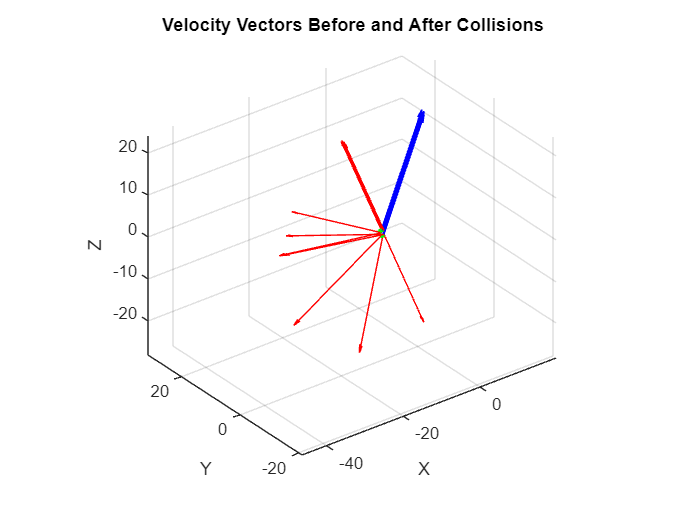

% Create a figure and axis
figure;
axis equal;

%arrays for angles
incident_angles = zeros([length(ParticleNo) 1]);
reflected_angles = zeros([length(ParticleNo) 1]);
% Loop through each set of components and plot the vector
hold on;
for i = 1:length(ParticleNo)
    quiver3(CollisionLocationX(i,1), CollisionLocationY(i,1), CollisionLocationZ(i,1), VelocityBeforeCollisionX(i,1), VelocityBeforeCollisionY(i,1), VelocityBeforeCollisionZ(i,1), 'b');
    quiver3(CollisionLocationX(i,1), CollisionLocationY(i,1), CollisionLocationZ(i,1), VelocityAfterCollisionX(i,1), VelocityAfterCollisionY(i,1), VelocityAfterCollisionZ(i,1), 'r');
    quiver3(CollisionLocationX(i,1), CollisionLocationY(i,1), CollisionLocationZ(i,1), CollisionNormalX(i,1), CollisionNormalY(i,1), CollisionNormalZ(i,1), 'g');
    incident_angles(i,1) = 180-calculate_angle_between_vectors([CollisionNormalX(i,1), CollisionNormalY(i,1), CollisionNormalZ(i,1)], [VelocityBeforeCollisionX(i,1), VelocityBeforeCollisionY(i,1), VelocityBeforeCollisionZ(i,1)]);
    reflected_angles(i,1) = calculate_angle_between_vectors([VelocityAfterCollisionX(i,1), VelocityAfterCollisionY(i,1), VelocityAfterCollisionZ(i,1)], [CollisionNormalX(i,1), CollisionNormalY(i,1), CollisionNormalZ(i,1)]);
end
hold off;

% Set the axis labels
xlabel('X');
ylabel('Y');
zlabel('Z');

% Set the title
title('Velocity Vectors Before and After Collisions');

% Grid on
grid on;
view(-37.5, 30);

%legend('Velocity Before Collision', 'Velocity After Collision', 'Collision Normal');

%show angles
disp('Incident angles are: ');

Incident angles are: 


disp(incident_angles);

   18.2967
   37.7579
   67.1908
   38.2022
   22.8088
   67.1914
   48.3503
   67.1919
   42.9140
    4.7506
   67.1925



disp('Reflected angles are: ');

Reflected angles are: 


disp(reflected_angles);

   18.2966
   37.7579
   67.1908
   38.2022
   22.8088
   67.1914
   48.3503
   67.1919
   42.9140
    4.7506
   67.1925



function angle_degrees = calculate_angle_between_vectors(vector1, vector2)
    % Calculate the dot product of the two vectors
    dot_product = dot(vector1, vector2);
    
    % Calculate the magnitudes of the two vectors
    magnitude1 = sqrt(sum(vector1.^2));
    magnitude2 = sqrt(sum(vector2.^2));
    
    % Calculate the cosine of the angle between the two vectors
    cos_angle = dot_product / (magnitude1 * magnitude2);
    
    % Calculate the angle between the two vectors (in radians)
    angle_radians = acos(cos_angle);
    
    % Convert the angle to degrees
    angle_degrees = rad2deg(angle_radians);
end